% Define the time vector
t = linspace(0, 2*pi, 1000);

% Define the original signal x(t)
x = sin(t);  % Original signal

% Define an approximated signal x_hat(t)
x_hat = sin(t) + 0.1 * randn(size(t));  % Approximated signal with some noise

% Compute the Mean Square Error (MSE)
mse = mean((x - x_hat).^2);

% Display the result
disp(['Mean Square Error (MSE): ', num2str(mse)]);

Mean Square Error (MSE): 0.00998


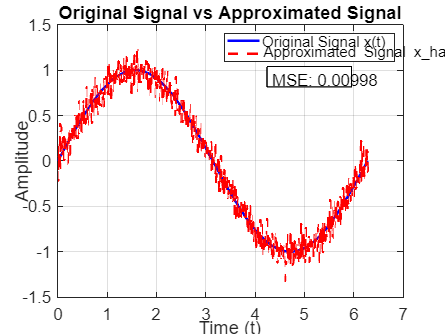


% Plot the original signal and the approximated signal
figure;
plot(t, x, 'b', 'LineWidth', 1.5);
hold on;
plot(t, x_hat, 'r--', 'LineWidth', 1.5);
title('Original Signal vs Approximated Signal');
xlabel('Time (t)');
ylabel('Amplitude');
legend('Original Signal x(t)', 'Approximated Signal x\_hat(t)');
grid on;

% Annotation on the plot
annotation('textbox', [0.6, 0.7, 0.3, 0.1], 'String', ['MSE: ', num2str(mse)], 'FitBoxToText','on', 'BackgroundColor','white');